## Lab2 Report

## Students :

- Ivar Jönsson ivajns-9

### Task 1

Analytically argue that if the coefficients of the difference equation are real, and z = a + ib

is a complex valued singularity, then its conjugate, a − ib also has to be a singularity.

The system has singularites on one the polynomials roots, ( The system can be described as a division of two polynomials ), using the fact that a polynomial with real valued coeficiant that has a complex root also has a root in the complex cojugate of that same complex number leads us to the conclusion that if a complex number is a singularity for a system then the complex conjugate of that number also has to bee a singularity.

### Task 2

Open PZlab, and place a zero at z = 0.5. Is the resulting system causal? If not, add another

singularity to make it causal. Hint: Both (z − a) and (1 − a/z) have a zero at z = a

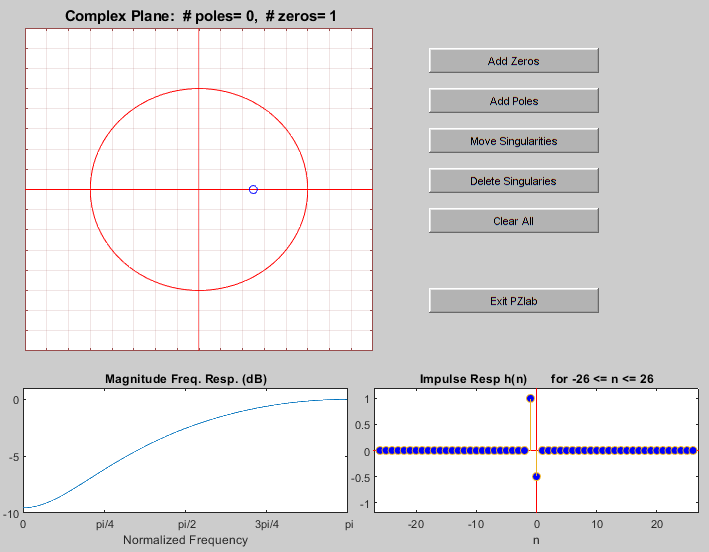

% A zero at real = .5
z = [0.5];
% No poles to initiate
p = [];
pzlab(p,z)

This is not a casual system since it depends on n values less than 0, adding a pole in the orging at z=0 solves this issue

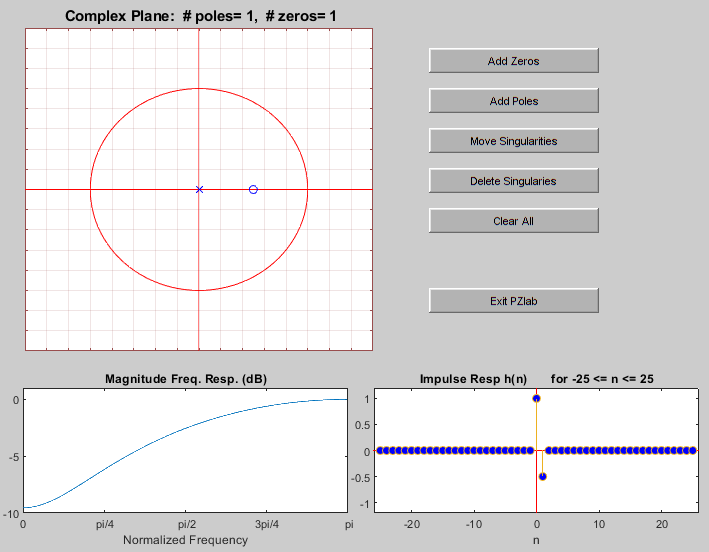

pzlab([0],z)

### Task 3

Move the zero at z = 0.5, progressively in steps towards the point z = 1. Describe the

changes in the systems frequency response. Please note that since we only consider difference

equations with real valued coefficients, the frequency response has symmetries that yield that

it is sufficient to study the response for frequencies 0 ≤ ω ≤ π.

for zero = 0.5:.1:1
    % Not actually going to plot it for the hand in, if you want to plot it
    % then go ahead
    %pzlab(p,[zero])
end

We can se that the frequenzy response gets steeper and acts like a more agressive high pass filter moving the cut off frequenzy closer and closer to 0 for every step, moving it along the real axis does not decrease the gain for other parts of the frequenzy response much.

### Task 4

Move the zero at z = 1, progressively in steps counter clockwise around the unit circle.

Again, describe the change in the systems frequency response. At what frequency does the

null appear?

for angle = 0:pi/20:pi
    % Not actually going to plot it for the hand in, if you want to plot it
    % then go ahead
    %pzlab(p,[cos(angle)+i*sin(angle),cos(angle)-i*sin(angle)])
end

It becomes a band stop filter, it stops a very small frequenzy band just around the angle on which the root is placed, so if the angle of the complex number is pi/4 then the frequency response nulls all signals with the frequnzy pi/4

### Task 5

Clear all singularities, now repeat steps 2-4 with a pole instead of a zero.

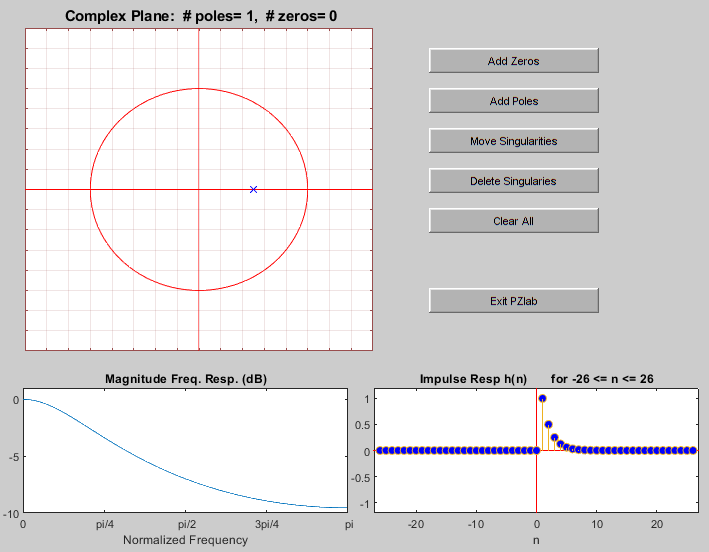

% A zero at real = .5
z = [0.5];
% No poles to initiate
p = [];
pzlab(z,p)

for zero = 0.5:.1:1
    % Not actually going to plot it for the hand in, if you want to plot it
    % then go ahead
    %pzlab([zero],p)
end
for angle = 0:pi/20:pi
    % Not actually going to plot it for the hand in, if you want to plot it
    % then go ahead
    %pzlab([cos(angle)+1i*sin(angle),cos(angle)-1i*sin(angle)],p)
end

For comments see task 6

### Task 6

Comment in general what happens to the frequency response with respect to the pole locations and the zero locations.

A pole at im(z) = 0 on the unit circle makes the system null for every frequenzy. Using a pole instead of a zero makes the system act like a band pass filter instead of a band stopp filter, meaning that it allows a certain frequency pass through almost un touched, using a few of these would be a great way to filter out noise in audio signals and only allowing audible signals to pass through. Using zeros causes the system to act like a band stop filter stopping the filter from passing anny signals of that specific frequency. Both the poles and zeros mainly affect the signals with a frequnzy equal to the angle of the complex number where the pole/zero is located.

Moving along the real axis makes the system act like a more agressive low pass filter, the closer we get to the unit circle the more agressive it gets.

### Task 7

Try to design a causal notch filter that nulls out any input at ω = π/4 , by placing a root on the unit circle at the appropriate location. What is the corresponding input/output difference equation?

simple 

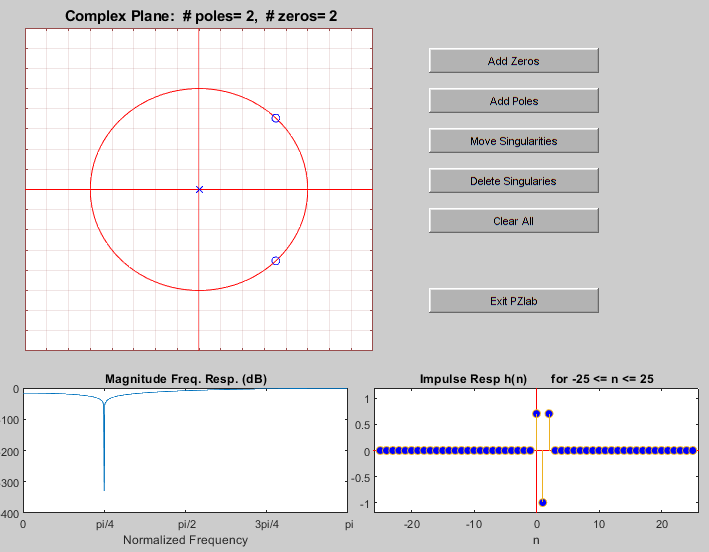

angle = pi/4;
% We need 2 poles in the center since we have too roots for 1/n as in task
% 2
pzlab([0,0],[cos(angle)+1i*sin(angle),cos(angle)-1i*sin(angle)])


$$y\left(n\right)=\ldotp \bar{707\ldotp } \ldotp \ldotp x\left\lbrack n\right\rbrack -1x\left\lbrack n-1\right\rbrack +\ldotp 0\bar{\ldotp 7070} \;x\left\lbrack n-2\right\rbrack$$


### Task 8

Improve your notch filter to make the notch narrower and steeper. Also, we’d like to have a very flat response everywhere else! Hint: try placing a couple of poles on both sides of your zero. Perhaps you’ll need other singularities strategically located. Print out your resulting filter, and describe your efforts and results.

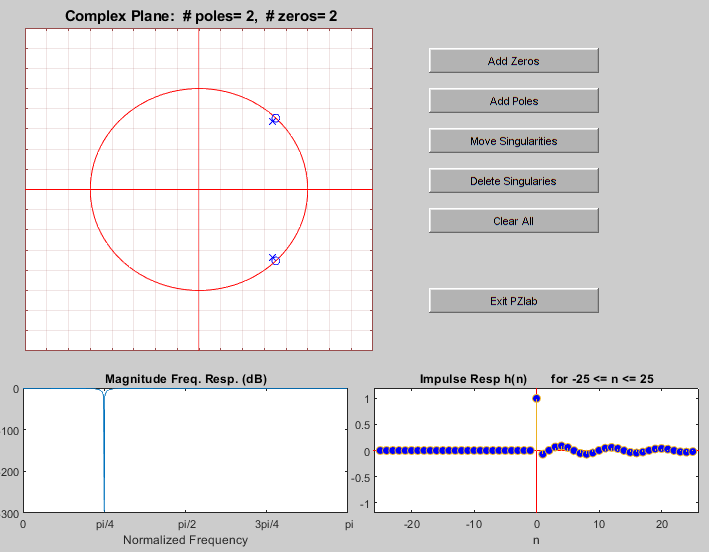

angle = pi/4;
first_offset = pi/50;
% Define a complex number handle that returns both the complex conjugate
% and the normal complex number, given an angle and a scale
complexnumber = @(angle,scale)[scale.*(cos(angle)+1i*sin(angle)),scale.*(cos(angle)-1i*sin(angle))];
zero1 = complexnumber(pi/4,1);
comp_pole = complexnumber(pi/4,.95);

pzlab([comp_pole],[zero1])

First we add the 2 poles verry close to the zero, then we add zeros at the exact same angle just a little bit inside of the unit circle, as to not dampen the rest of the response.

### Task 9

Assuming a sampling frequency of 44,100 Hz, (Ωs = 2π ·44.1 ·103 rad/s):

(a) Use PZlab to design a filter that notches out the frequencies 500 Hz, 2000 Hz, 5000 Hz, but has nice peaks at 1000 Hz, and 8000 Hz.

sampeling_scaler = 44.1*10^3

sampeling_scaler = 44100

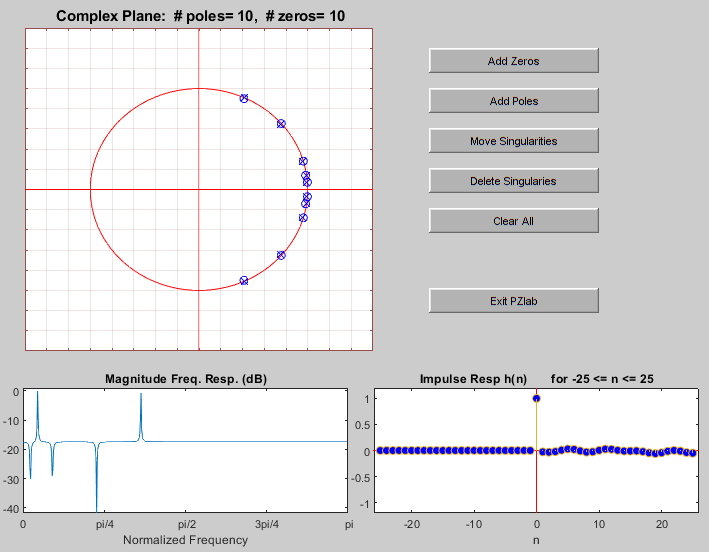

freqs = [500,2000,5000,1000,8000];
normalized_freqs = 2.*pi.*freqs./sampeling_scaler;
offset = .99;
zeros = [
    % Null the target freqs
    complexnumber(normalized_freqs(1),1)' 
    complexnumber(normalized_freqs(2),1)' 
    complexnumber(normalized_freqs(3),1)' 
    % Complementary poles to make the slope more aggresive
    complexnumber(normalized_freqs(4),offset)'
    complexnumber(normalized_freqs(5),offset)'
    ];
poles = [
    % Complementary poles to make the slope more aggressive
    complexnumber(normalized_freqs(1),offset)' 
    complexnumber(normalized_freqs(2),offset)' 
    complexnumber(normalized_freqs(3),offset)' 
    % Amplify the target freqs
    complexnumber(normalized_freqs(4),1)'
    complexnumber(normalized_freqs(5),1)'
    ];
pzlab(poles',zeros')

(b) Create the vector of associated coefficients from the saved pole and zero locations (located in the file `PZoutput`, created when exiting PZlab).

Done from part a

(c) Use the command wavread, to read-in the wavfile `black.wav` (located on the course webpage), or any other audio clip of your choice. You may wish to read in only a few seconds of the file to reduce processing time (see `help wavread`).

[sig,Fs]= audioread("black.wav");

(d) Use the `filter` command, to process the sound with your designed system.

data = filter(real(poles),real(zeros),sig);

(e) listen to you results for instance using the `sound` command. You may have to save your results as a wavfile, and then use whatever tool available to listen to the sound

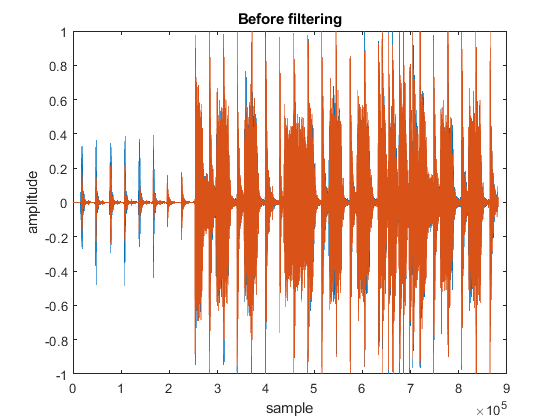

%soundsc(data)
sound(data, 44100);
figure()
plot(sig);
xlabel("sample");
ylabel("amplitude");
title("Before filtering");

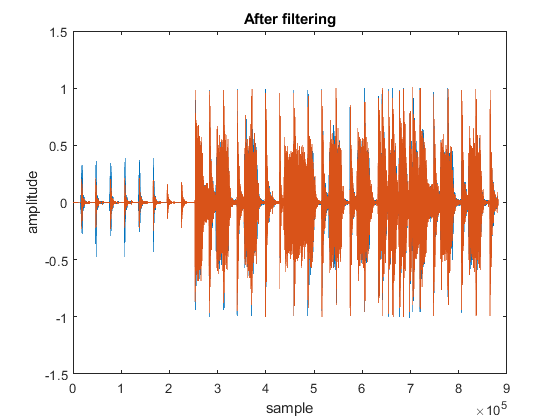

figure()
plot(data);
xlabel("sample");
ylabel("amplitude");
title("After filtering");